## **気温の変化率の求め方**

ここでは，Mission3 で使用する，高度に対する気温の変化率の求め方を説明します．ここで使用するデータは，Mission3 でロードした，下記の 2つです．

- height_m3         : 高度

- temp_m3           : 気温

load mission3_data.mat height_m3 temp_m3

Mission2 で，高度に対する気温の変化率を求めた時は，下記のように求めましたね．


$$\textrm{気温の変化率}\;=\;\frac{\;\;\textrm{気温の変化量}\;\;\;}{\;\;\;\;\;\textrm{高度の変化量}\;\;\;\;\;\;}$$


ということは，隣り合うデータについて，気温の差，高度の変化量を求めて，気温の変化量を高度の変化量で割ってあげると，隣り合うデータとの気温の変化率が求められます．隣り合うデータとの差を求めるには，`diff` 関数を使います．

例えば，下図のようなデータがあるとしましょう．

x = [1 2 3 4 5]

x =      1     2     3     4     5


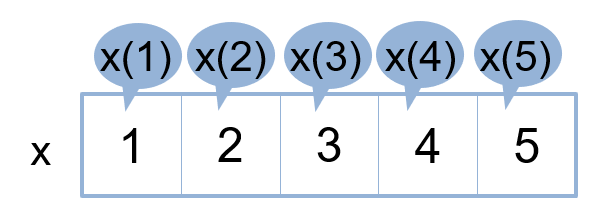

このデータの，隣り合うデータ同士の差分はどう求めますか？

x(2) - x(1)

ans = 1

x(3) - x(2)

ans = 1

といった感じに，隣り合うデータを引いていきますね．これを沢山のデータがある場合にも，計算してくれる関数が `diff` です．

試しに，実行してみましょう．

diffx = diff(x)

diffx =      1     1     1     1


参考：[`diff`](matlab:doc('diff'))

上記情報を元に，気温と高度の変化量を求めてみましょう．

height_diff = diff(height_m3)  % 気温の変化量

height_diff =   335.6000
  216.9000
  385.9000
  311.4000
  280.9000
  369.5000
  323.6000
  321.4000
  322.2000
  302.5000


temp_diff   = diff(temp_m3)    % 高度の変化量

temp_diff =    -1.8200
   -1.5600
   -1.7600
   -0.9600
   -0.7600
   -1.0900
   -0.6600
   -0.4600
   -1.7700
   -1.7100


次に，各要素について，気温の変化量を高度の変化量で割ることで，気温の変化率が求まります．

grad_temp_m3_exp = temp_diff ./ height_diff

grad_temp_m3_exp =    -0.0054
   -0.0072
   -0.0046
   -0.0031
   -0.0027
   -0.0029
   -0.0020
   -0.0014
   -0.0055
   -0.0057


[Mission3に戻る](matlab:closeAndMove("sbda_mission3.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.